# Nonlinear Identification Method fmincon

This text will function as an example to the real identification method. We will create a simple arbitrary function, which we will attempt to approximate using the *fmincon* method provided by Matlab.

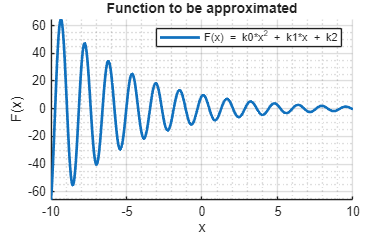

clear; close all;
clc;

% Function parameters
k0 = 5;
k1 = 4;
k2 = 1.2;
Ku = 1/1520;

% Create a simple function to be approximated
F = @(x, u) 10*exp(-x/k0).*sin(k1 * x + k2) + Ku*u;

% Define a range of x values for approximation
X = -10:0.05:10;
U = zeros(size(X));
% U = 10000*cos(2*pi*10*X);

% Evaluate the function F at the defined x values
Y = F(X, U);

% Plot the function approximation
figure(1);
hold on;
plot(X, Y, 'LineWidth', 2);
grid minor;
grid on;
xlabel('x');
ylabel('F(x)');
title('Function to be approximated');
% Add a legend to the plot
legend('F(x) = k0*x^2 + k1*x + k2');
hold off;


fprintf("Let us now try to approximate the function: ");

Let us now try to approximate the function: 

disp('F(x) = k0*x^2 + k1*x + k2');

F(x) = k0*x^2 + k1*x + k2


fprintf("Using the fmincon method.\n");

Using the fmincon method.


Starting parallel pool (parpool) using the 'BEAST' profile ...
Connected to parallel pool with 24 workers.


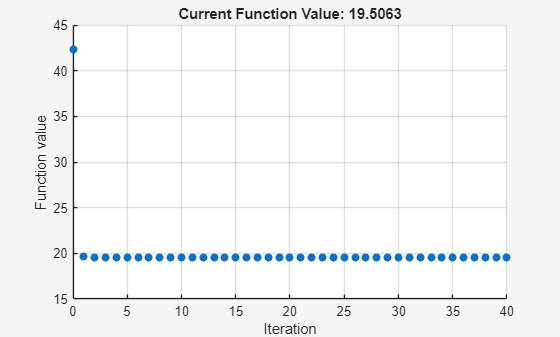


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


g =   334.2533  165.6574  -16.9344    1.0000


% Define the optional parameters for the fmincon method, to display the
% approximation progress. (Fitness function evolution)
options = optimset('PlotFcns', @optimplotfval, 'UseParallel', true, 'TolFun', 1e-10);

Funknown = @(u, x, p) 10*exp(-x/p(1)).*sin(p(2) * x + p(3)) + p(4)*u;

function [y] = Fitertest(f, x, X, U)
    y = zeros(size(X));
    for i=1:length(X)
        y(i) = f(U(i), X(i), x);
    end
end

% Define the cost function for fmincon
J = @(x, params) sqrt(mean((Y - Fitertest(Funknown, x, X, U)).^2));

% Initial guess for the parameters [a, b, c]
g0 = [3.0000  4    1.9416    1.0000]; % guess_0

g = fmincon(J,g0,[],[],[],[],[],[],[],options)



% Display the optimized parameters
fprintf('Optimized parameters: k0 = %.4f, k1 = %.4f, k2 = %.4f, Ku = %.4n', g(1), g(2), g(3), g(4));

Optimized parameters: k0 = 334.2533, k1 = 165.6574, k2 = -16.9344, Ku = 

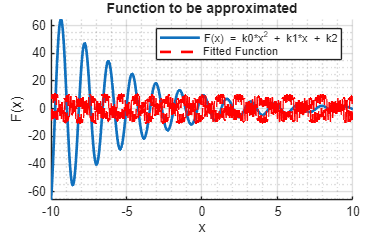


% Calculate the fitted function values using the optimized parameters
fittedY = Funknown(U, X, g);
% Plot the fitted function alongside the original function
figure(1);
hold on;
plot(X, fittedY, '--r', 'LineWidth', 2);
legend('F(x) = k0*x^2 + k1*x + k2', 'Fitted Function');
hold off;


% Calculate the residuals between the original and fitted function values
residuals = Y - fittedY;

% Display the mean squared error of the fit
mse = mean(residuals.^2);
fprintf('Mean Squared Error of the fit: %.4f\n', mse);

Mean Squared Error of the fit: 380.4960
